% clear
name = getenv('COMPUTERNAME'); 
if name == 'DESKTOP-9DDE2RH'
    image_dir = '\\storage1.ris.wustl.edu\crponce\Active\Stimuli\2019-06-Evolutions\beto-190610a'
    code_dir = '\\storage1.ris.wustl.edu\crponce\Active\Stimuli\2019-06-Evolutions\beto-190610a'
else
    image_dir = 'D:\Monkey_Data\2019-06-Evolutions\beto-190610a\BACKUP_3';
    code_dir = 'D:\Monkey_Data\2019-06-Evolutions\beto-190610a';
end

image_dir = '\\storage1.ris.wustl.edu\crponce\Active\Stimuli\2019-06-Evolutions\beto-190610a'

code_dir = '\\storage1.ris.wustl.edu\crponce\Active\Stimuli\2019-06-Evolutions\beto-190610a'

% image_dir = 'D:\Monkey_Data\2019-06-Evolutions\beto-190610a\BACKUP_3';
% code_dir = 'D:\Monkey_Data\2019-06-Evolutions\beto-190610a';
% imglist = ls([image_dir,'\block*.jpg']);
% codelist = ls([code_dir,'\block*.mat']);
imglist = dir(fullfile(image_dir, 'block*.jpg'));
img_fn = {imglist.name};
img_fullfn = fullfile(image_dir, {imglist.name});
codelist = dir(fullfile(code_dir, 'block*.mat'));
code_fn = {codelist.name};
code_fullfn = fullfile(code_dir, {codelist.name});

score_arr = [];
id_arr = {};
code_arr = [];
for i =1:numel(code_fullfn)
   data = load(code_fullfn{i});
   code_arr = cat(1, code_arr, data.codes);
   id_arr = cat(2, id_arr, data.ids);
   if i~=1
       score_arr = cat(1, score_arr, data.scores);
   end
   if i == numel(code_fullfn)
       score_arr = cat(1, score_arr, nan([length(data.ids), 1]));
   end
end
generation_id = ceil( ((1:size(code_arr,1)) - 30 + 1)/40);

tic
code_dist = pdist(code_arr);
toc
tic
code_coord3 = mdscale(code_dist, 3);
toc % Elapsed time is 2374.430649 seconds.

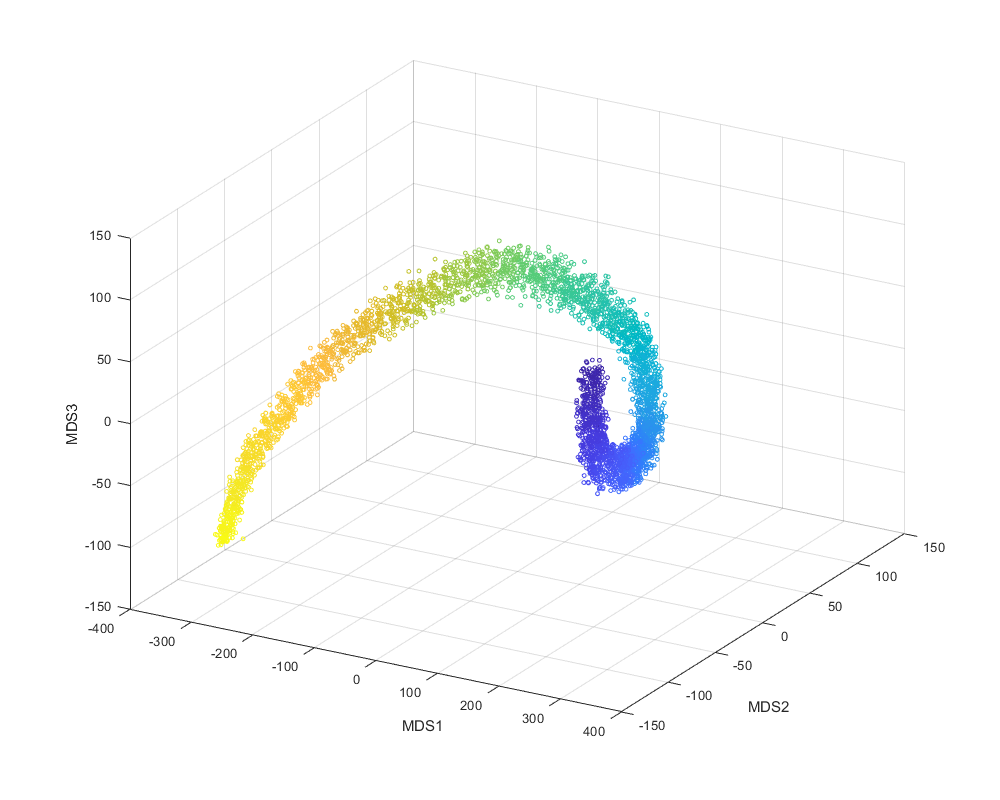

figure('Position',[0,0,1000,800])
scatter3(code_coord3(:,1),code_coord3(:,2),code_coord3(:,3),9,generation_id)
xlabel("MDS1")
ylabel("MDS2")

zlabel("MDS3")
view([30 29])

save('dimen_red_coord.mat','code_coord3','-append')

[PC_axiss,code_PC,PC_var,~,var_explained] = pca(code_arr,'NumComponents',30);

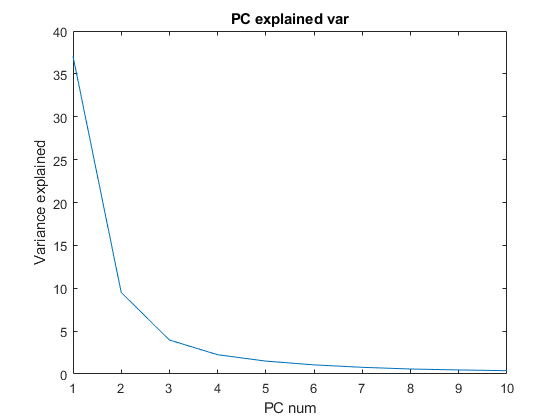

figure()
plot(var_explained(1:10))

title("PC explained var")
ylabel("Variance explained")
xlabel("PC num")

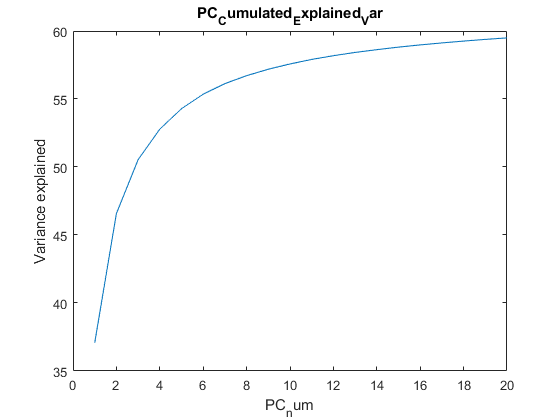

figure()
plot(cumsum(var_explained(1:20)))
title("PC Cumulated Explained Var")

ylabel("Variance explained")
xlabel("PC num")

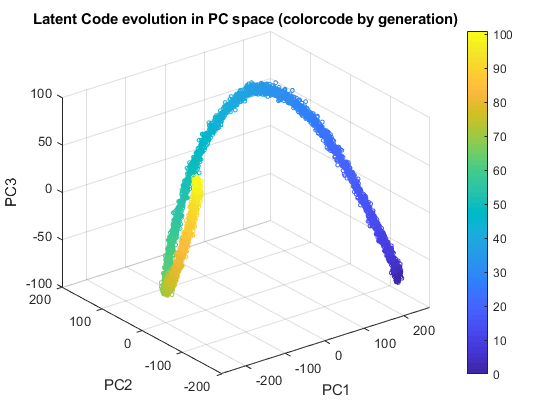

figure(2)%'Position',[0,0,1000,800]
scatter3(code_PC(:,1),code_PC(:,2),code_PC(:,3),9,generation_id)
xlabel("PC1")
ylabel("PC2")
zlabel("PC3")
colorbar()

title("Latent Code evolution in PC space (colorcode by generation)")

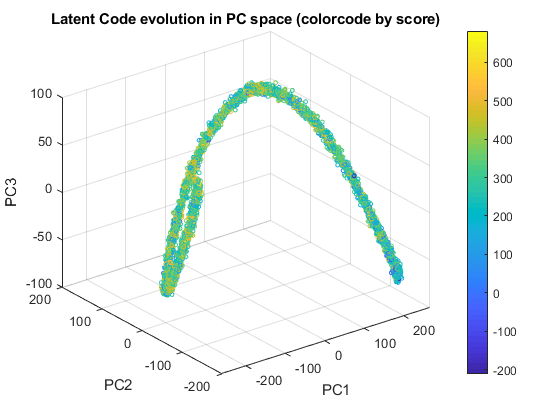

figure(3)%'Position',[0,0,1000,800]
scatter3(code_PC(:,1),code_PC(:,2),code_PC(:,3),9,score_arr)
xlabel("PC1")
ylabel("PC2")
zlabel("PC3")
colorbar()
title("Latent Code evolution in PC space (colorcode by score)")

save('dimen_red_coord.mat','code_PC','-append')

code_dist_mat = squareform(code_dist);
group_dist_matrix()

figure()
imagesc(group_dist_mat)
xlabel("generation id")
ylabel("generation id")
axis equal tight
colorbar()
title("Average Distance Matrix among Generation (latent code L2)")

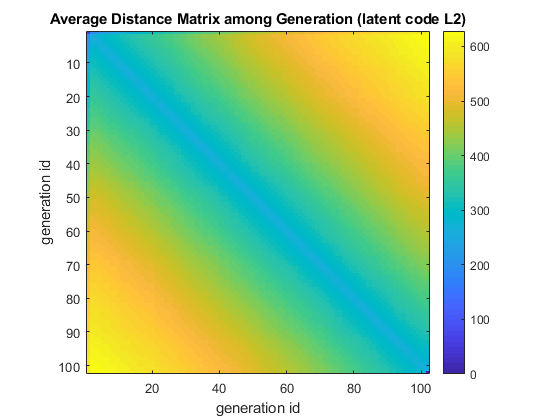

tic
imgs = {};

img_arr = [];
for i = 1:numel(img_fullfn)
    imgs{i} = imread(img_fullfn{i});
    %img_arr = cat(1, img_arr, imgs{i}(:)');
end
toc

tic

Elapsed time is 223.150525 seconds.


img_dist_mat = zeros(numel(imgs))
for i = 1:numel(imgs)
    for j = i+1:numel(imgs)

img_dist_mat =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

        img_dist_mat(i,j) = norm(single(imgs{j}(:) - imgs{i}(:)));
        img_dist_mat(j,i) = img_dist_mat(i,j); 
    end
end
img_group_dist_mat = group_dist_matrix(img_dist_mat, generation_id);
toc % Elapsed time is 1829.197157 seconds.

figure()
imagesc(img_group_dist_mat)

Elapsed time is 1829.197157 seconds.


xlabel("generation_id")
ylabel("generation_id")
axis equal tight
colorbar()
title("Average Distance Matrix among Generation (pixel space L2)")

save('dist_mat.mat','img_dist_mat');%,'-append')

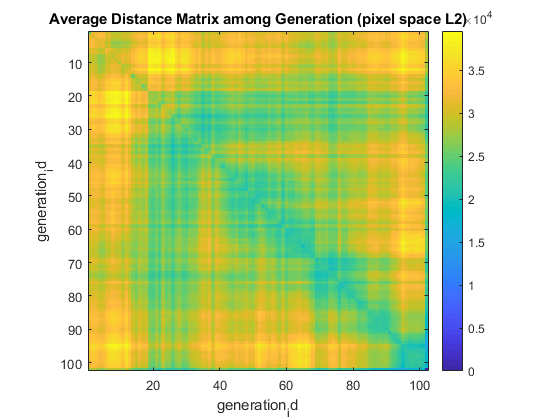

tic
img_arr = zeros([size(code_arr,1), length(imgs{1}(:))],"uint8");

for i = 1:numel(img_fullfn)
    img_arr(i,:) = imgs{i}(:)';
end
toc

tic
% img_arr = double(img_arr);
% [img_PC_axiss,image_PC] = pca(img_arr,"NumComponents",15,"Economy",true); % this will cause error
toc

tic

Elapsed time is 4.098321 seconds.


[img_vec,sval,img_PC_axiss] = svds(double(img_arr),10);
image_PC = img_vec*sval;
toc 

save('image_svd.mat','img_vec','sval','img_PC_axiss')

figure()%'Position',[0,0,1000,800]
scatter3(image_PC(:,1),image_PC(:,2),image_PC(:,3),9,score_arr)
xlabel("PC1")
ylabel("PC2")
zlabel("PC3")
colorbar()

Elapsed time is 39.655288 seconds.


axis equal
title("Image evolution in PC space (colorcode by score)")

view([116 28])

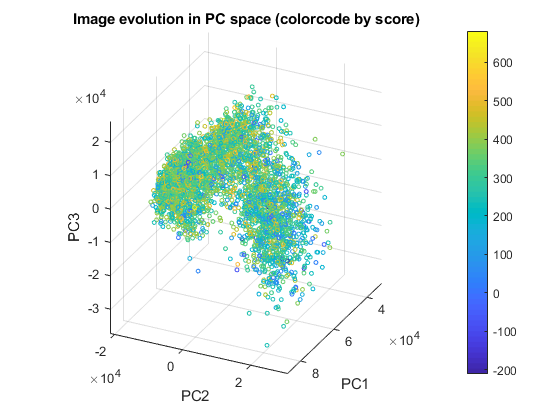

figure()%'Position',[0,0,1000,800]
scatter3(image_PC(:,1),image_PC(:,2),image_PC(:,3),9,generation_id)
xlabel("PC1")
ylabel("PC2")
zlabel("PC3")
colorbar()
axis equal
title("Image evolution in PC space (colorcode by generation id)")


view([116 28])

figure()
imagesc(200*reshape(img_PC_axiss(:,1),size(imgs{1})))
xticks([])
yticks([])
axis equal tight

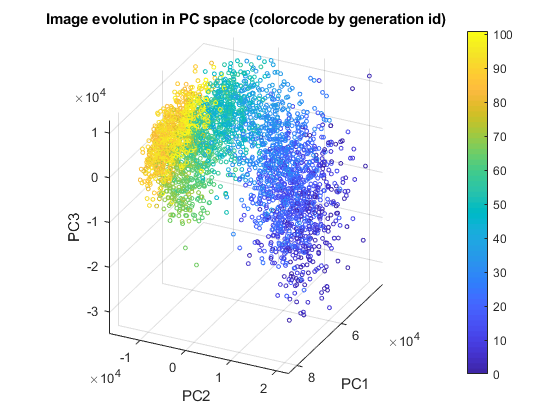

TotalPC = 10;
figure("Position",[0,0,2200,450])
for PC_id = 1:TotalPC
    subplot(2,TotalPC,PC_id)
    imagesc(200*reshape( img_PC_axiss(:,PC_id),size(imgs{1})))

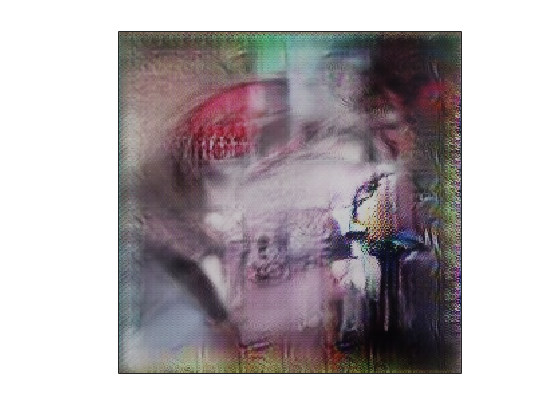

    title(sprintf("PC%d: %.3e",PC_id,sval(PC_id, PC_id)))
    xticks([])
    yticks([])
    axis equal tight
    if PC_id == 1
        ylabel("Excitatory")

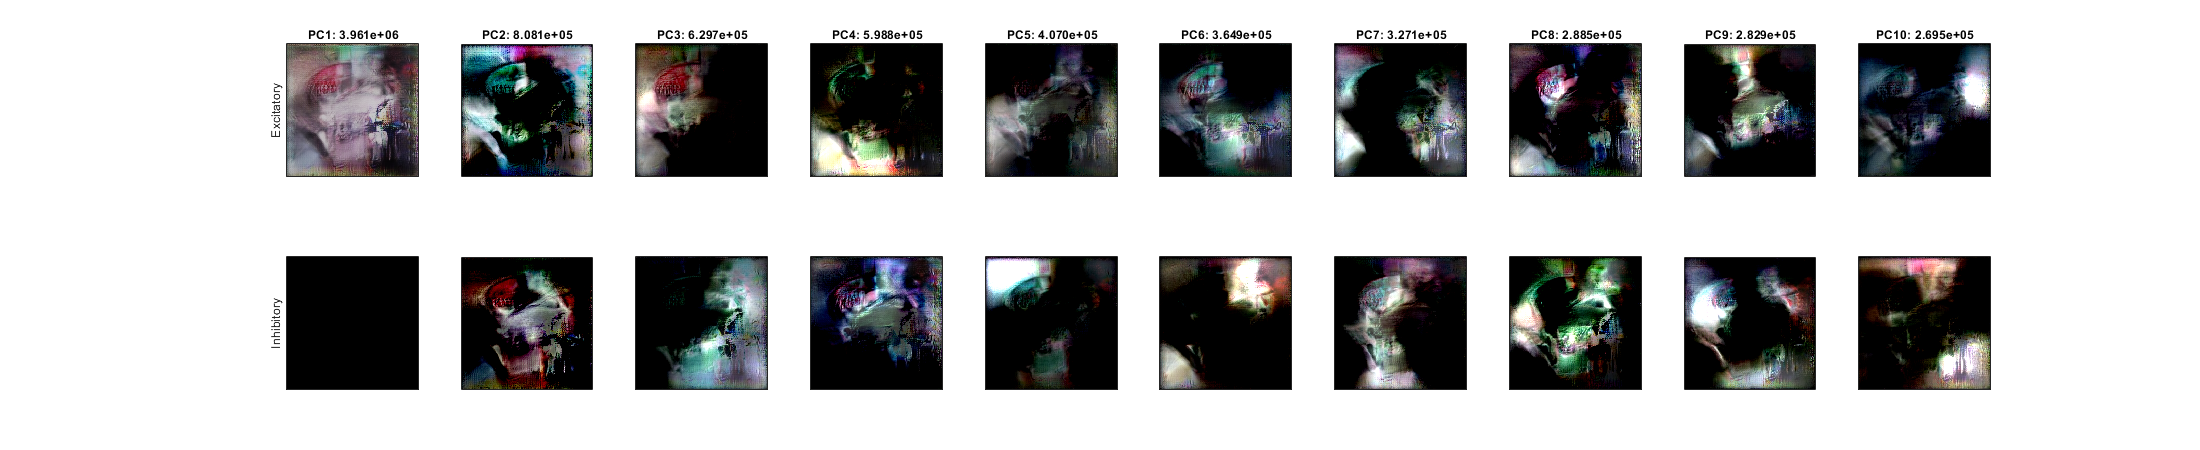

    end
    subplot(2,TotalPC,PC_id+TotalPC)
    imagesc(200*reshape( - img_PC_axiss(:,PC_id),size(imgs{1})))
    xticks([])
    yticks([])
    axis equal tight
    if PC_id == 1
        ylabel("Inhibitory")
    end
end

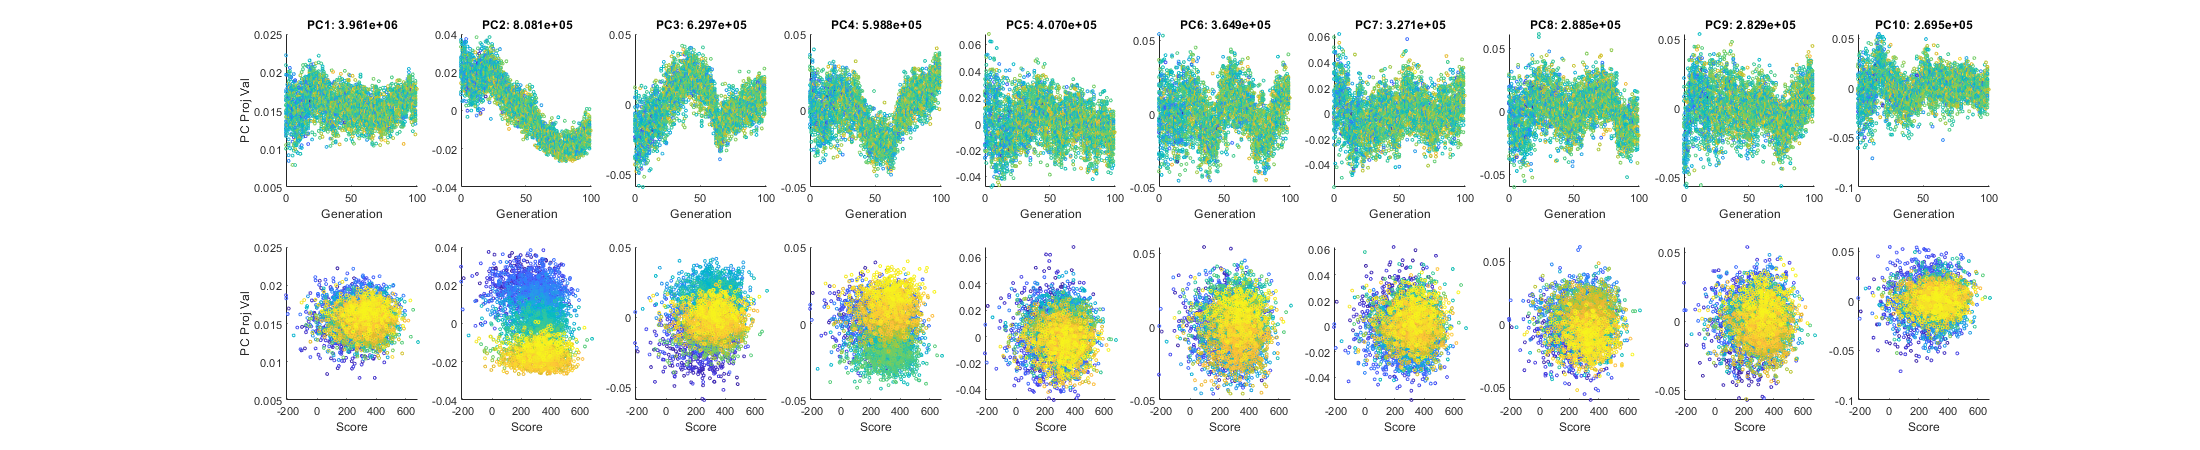

figure("Position",[0,0,2200,450])
for PC_id = 1:TotalPC
    subplot(2,TotalPC,PC_id)
    scatter(generation_id,img_vec(:,PC_id),5,score_arr)
    xlabel("Generation")
    if PC_id==1
    ylabel("PC Proj Val")
    end
    title(sprintf("PC%d: %.3e",PC_id,sval(PC_id, PC_id)))
    subplot(2,TotalPC,PC_id+TotalPC)
    scatter(score_arr,img_vec(:,PC_id),5,generation_id)
    xlabel("Score")
    if PC_id==1
    ylabel("PC Proj Val")
    end
end

function group_dist_mat = group_dist_matrix(code_dist_mat, generation_id)
groups = unique(generation_id);
group_dist_mat = zeros(numel(groups));
for i = 1:numel(groups)
    for j = 1:numel(groups)
        id_i = groups(i);
        id_j = groups(j);
        group_dist_mat(i,j) = mean(code_dist_mat(generation_id==id_i, generation_id==id_j),"all");
    end
end
end